clear
clc
%intialize all input
x_int = [0.0608; 0.1198; 0.1813]

x_int =     0.0608
    0.1198
    0.1813


nfrom = [1; 2; 3; 4; 4; 5; 6; 7; 8];
nto   = [4; 8; 6; 5; 9; 6; 7; 8; 9];
yb    = [ ...
    -1i*17.3611;
    -1i*16.0;
    -1i*17.0648;
    1.9423 - 1i*10.5106;
    1.3652 - 1i*11.6041;
    1.2819 - 1i*5.5882;
    1.1546 - 1i*9.7843;
    1.6164 - 1i*13.6981;
    1.1874 - 1i*5.9752];
P = [0.723; 1.630; 0.850; -0.000; -0.900; -0.000; -1.000; -0.000; -1.250];
Q = [0.812; 0.534; 0.387;  0.000; -0.300;  0.000; -0.350;  0.000; -0.500];

V_mag = [1.0400; 1.0253; 1.0254; 0.9958; 0.9664; 1.0045; 0.9795; 0.9977; 0.9509];

V_ang = [0.0000; 9.6842; 4.8745; -2.3057; -3.7371; 2.1026; 0.8329; 3.9686; -4.1379];

gen_index = [1; 2; 3];
load_index = [4; 5; 6; 7; 8; 9];
fault_bus = [6];
nf_from = [5];
nf_to = [6];

[E_mag, E_ang] = machineVoltage(P, Q, V_mag, V_ang, x_int,gen_index)

E_mag =     1.0883
    1.1042
    1.1041


E_ang =     0.0388
    0.3424
    0.2216


YPf = admittancePF(nfrom, nto, yb)

YPf =    0.0000 -17.3611i   0.0000 + 0.0000i   0.0000 + 0.0000i   0.0000 +17.3611i   0.0000 + 0.0000i   0.0000 + 0.0000i   0.0000 + 0.0000i   0.0000 + 0.0000i   0.0000 + 0.0000i
   0.0000 + 0.0000i   0.0000 -16.0000i   0.0000 + 0.0000i   0.0000 + 0.0000i   0.0000 + 0.0000i   0.0000 + 0.0000i   0.0000 + 0.0000i   0.0000 +16.0000i   0.0000 + 0.0000i
   0.0000 + 0.0000i   0.0000 + 0.0000i   0.0000 -17.0648i   0.0000 + 0.0000i   0.0000 + 0.0000i   0.0000 +17.0648i   0.0000 + 0.0000i   0.0000 + 0.0000i   0.0000 + 0.0000i
   0.0000 +17.3611i   0.0000 + 0.0000i   0.0000 + 0.0000i   3.3075 -39.4758i  -1.9423 +10.5106i   0.0000 + 0.0000i   0.0000 + 0.0000i   0.0000 + 0.0000i  -1.3652 +11.6041i
   0.0000 + 0.0000i   0.0000 + 0.0000i   0.0000 + 0.0000i  -1.9423 +10.5106i   3.2242 -16.0988i  -1.2819 + 5.5882i   0.0000 + 0.0000i   0.0000 + 0.0000i   0.0000 + 0.0000i
   0.0000 + 0.0000i   0.0000 + 0.0000i   0.0000 +17.0648i   0.0000 + 0.0000i  -1.2819 + 5.5882i   2.4365 -32.4373i  -1.1546 + 9.7843i 

Y1_prim_prim = Y_prefault_unreduced(YPf, x_int, gen_index)

Y1_prim_prim =    0.0000 -33.8085i   0.0000 + 0.0000i   0.0000 + 0.0000i   0.0000 +17.3611i   0.0000 + 0.0000i   0.0000 + 0.0000i   0.0000 + 0.0000i   0.0000 + 0.0000i   0.0000 + 0.0000i   0.0000 +16.4474i   0.0000 + 0.0000i   0.0000 + 0.0000i
   0.0000 + 0.0000i   0.0000 -24.3472i   0.0000 + 0.0000i   0.0000 + 0.0000i   0.0000 + 0.0000i   0.0000 + 0.0000i   0.0000 + 0.0000i   0.0000 +16.0000i   0.0000 + 0.0000i   0.0000 + 0.0000i   0.0000 + 8.3472i   0.0000 + 0.0000i
   0.0000 + 0.0000i   0.0000 + 0.0000i   0.0000 -22.5805i   0.0000 + 0.0000i   0.0000 + 0.0000i   0.0000 +17.0648i   0.0000 + 0.0000i   0.0000 + 0.0000i   0.0000 + 0.0000i   0.0000 + 0.0000i   0.0000 + 0.0000i   0.0000 + 5.5157i
   0.0000 +17.3611i   0.0000 + 0.0000i   0.0000 + 0.0000i   3.3075 -39.4758i  -1.9423 +10.5106i   0.0000 + 0.0000i   0.0000 + 0.0000i   0.0000 + 0.0000i  -1.3652 +11.6041i   0.0000 + 0.0000i   0.0000 + 0.0000i   0.0000 + 0.0000i
   0.0000 + 0.0000i   0.0000 + 0.0000i   0.0000 + 0.0000i  -1.9423 +1

Y1_prim = Y_prefault_unreduced_ls(Y1_prim_prim, load_index, P, Q, V_mag)

Y1_prim =    0.0000 -33.8085i   0.0000 + 0.0000i   0.0000 + 0.0000i   0.0000 +17.3611i   0.0000 + 0.0000i   0.0000 + 0.0000i   0.0000 + 0.0000i   0.0000 + 0.0000i   0.0000 + 0.0000i   0.0000 +16.4474i   0.0000 + 0.0000i   0.0000 + 0.0000i
   0.0000 + 0.0000i   0.0000 -24.3472i   0.0000 + 0.0000i   0.0000 + 0.0000i   0.0000 + 0.0000i   0.0000 + 0.0000i   0.0000 + 0.0000i   0.0000 +16.0000i   0.0000 + 0.0000i   0.0000 + 0.0000i   0.0000 + 8.3472i   0.0000 + 0.0000i
   0.0000 + 0.0000i   0.0000 + 0.0000i   0.0000 -22.5805i   0.0000 + 0.0000i   0.0000 + 0.0000i   0.0000 +17.0648i   0.0000 + 0.0000i   0.0000 + 0.0000i   0.0000 + 0.0000i   0.0000 + 0.0000i   0.0000 + 0.0000i   0.0000 + 5.5157i
   0.0000 +17.3611i   0.0000 + 0.0000i   0.0000 + 0.0000i   3.3075 -39.4758i  -1.9423 +10.5106i   0.0000 + 0.0000i   0.0000 + 0.0000i   0.0000 + 0.0000i  -1.3652 +11.6041i   0.0000 + 0.0000i   0.0000 + 0.0000i   0.0000 + 0.0000i
   0.0000 + 0.0000i   0.0000 + 0.0000i   0.0000 + 0.0000i  -1.9423 +10.510

Y2_prim = Y_fault_unreduced_ls(Y1_prim, fault_bus) 

Y2_prim =    0.0000 -33.8085i   0.0000 + 0.0000i   0.0000 + 0.0000i   0.0000 +17.3611i   0.0000 + 0.0000i   0.0000 + 0.0000i   0.0000 + 0.0000i   0.0000 + 0.0000i   0.0000 +16.4474i   0.0000 + 0.0000i   0.0000 + 0.0000i
   0.0000 + 0.0000i   0.0000 -24.3472i   0.0000 + 0.0000i   0.0000 + 0.0000i   0.0000 + 0.0000i   0.0000 + 0.0000i   0.0000 +16.0000i   0.0000 + 0.0000i   0.0000 + 0.0000i   0.0000 + 8.3472i   0.0000 + 0.0000i
   0.0000 + 0.0000i   0.0000 + 0.0000i   0.0000 -22.5805i   0.0000 + 0.0000i   0.0000 + 0.0000i   0.0000 + 0.0000i   0.0000 + 0.0000i   0.0000 + 0.0000i   0.0000 + 0.0000i   0.0000 + 0.0000i   0.0000 + 5.5157i
   0.0000 +17.3611i   0.0000 + 0.0000i   0.0000 + 0.0000i   3.3075 -39.4758i  -1.9423 +10.5106i   0.0000 + 0.0000i   0.0000 + 0.0000i  -1.3652 +11.6041i   0.0000 + 0.0000i   0.0000 + 0.0000i   0.0000 + 0.0000i
   0.0000 + 0.0000i   0.0000 + 0.0000i   0.0000 + 0.0000i  -1.9423 +10.5106i   2.2605 -15.7776i   0.0000 + 0.0000i   0.0000 + 0.0000i   0.0000 + 0.000

Y3_prim = Y_post_unreduced_ls(Y1_prim, nf_from, nf_to, yb, nfrom, nto)

Y3_prim =    0.0000 -33.8085i   0.0000 + 0.0000i   0.0000 + 0.0000i   0.0000 +17.3611i   0.0000 + 0.0000i   0.0000 + 0.0000i   0.0000 + 0.0000i   0.0000 + 0.0000i   0.0000 + 0.0000i   0.0000 +16.4474i   0.0000 + 0.0000i   0.0000 + 0.0000i
   0.0000 + 0.0000i   0.0000 -24.3472i   0.0000 + 0.0000i   0.0000 + 0.0000i   0.0000 + 0.0000i   0.0000 + 0.0000i   0.0000 + 0.0000i   0.0000 +16.0000i   0.0000 + 0.0000i   0.0000 + 0.0000i   0.0000 + 8.3472i   0.0000 + 0.0000i
   0.0000 + 0.0000i   0.0000 + 0.0000i   0.0000 -22.5805i   0.0000 + 0.0000i   0.0000 + 0.0000i   0.0000 +17.0648i   0.0000 + 0.0000i   0.0000 + 0.0000i   0.0000 + 0.0000i   0.0000 + 0.0000i   0.0000 + 0.0000i   0.0000 + 5.5157i
   0.0000 +17.3611i   0.0000 + 0.0000i   0.0000 + 0.0000i   3.3075 -39.4758i  -1.9423 +10.5106i   0.0000 + 0.0000i   0.0000 + 0.0000i   0.0000 + 0.0000i  -1.3652 +11.6041i   0.0000 + 0.0000i   0.0000 + 0.0000i   0.0000 + 0.0000i
   0.0000 + 0.0000i   0.0000 + 0.0000i   0.0000 + 0.0000i  -1.9423 +10.510



%reduced matrix
Y1 = kron_reudction(Y1_prim, gen_index)

Y1 =   -0.6660 - 2.7446i  -0.6317 + 1.6187i  -0.4850 + 1.2891i
  -0.6317 + 1.6187i  -0.2692 - 2.6568i  -0.2876 + 1.1325i
  -0.4850 + 1.2891i  -0.2876 + 1.1325i  -0.1137 - 2.3533i


Y2 = kron_reudction(Y2_prim, gen_index)

Y2 =   -0.0288 - 3.5705i  -0.1722 + 0.8624i   0.0000 + 0.0000i
  -0.1722 + 0.8624i   0.0470 - 3.3377i   0.0000 + 0.0000i
   0.0000 + 0.0000i   0.0000 + 0.0000i   0.0000 - 4.1684i


Y3 = kron_reudction(Y3_prim, gen_index)

Y3 =   -1.0539 - 1.8865i  -0.6246 + 1.4159i  -0.3522 + 0.6063i
  -0.6246 + 1.4159i  -0.2540 - 2.6158i  -0.2581 + 1.2795i
  -0.3522 + 0.6063i  -0.2581 + 1.2795i  -0.0929 - 1.8399i



H = [23.64; 6.40; 3.01];
D = [9.6; 2.5; 1.0];
ws = 2 * pi * 60;
t_final = 5;
t_fault = 0;
t_clear = 0.12;
maxIter = 100;
P_m = electricPower(E_mag, Y1, E_ang);
x0 = [E_ang; zeros(length(E_ang),1)];
h = 0.001;
tol = 1e-5;

[t, x_hist, iter_hist] = solutionRoutine( ...
    x0, P_m, E_mag, ...
    Y1, Y2, Y3, ...
    H, D, ws, h, t_final, t_fault, t_clear, ...
    tol, maxIter)

t =          0    0.0010    0.0020    0.0030    0.0040    0.0050    0.0060    0.0070    0.0080    0.0090    0.0100    0.0110    0.0120    0.0130    0.0140    0.0150    0.0160    0.0170    0.0180    0.0190    0.0200    0.0210    0.0220    0.0230    0.0240    0.0250    0.0260    0.0270    0.0280    0.0290    0.0300    0.0310    0.0320    0.0330    0.0340    0.0350    0.0360    0.0370    0.0380    0.0390    0.0400    0.0410    0.0420    0.0430    0.0440    0.0450    0.0460    0.0470    0.0480    0.0490


x_hist =     0.0388    0.0388    0.0388    0.0388    0.0387    0.0386    0.0385    0.0384    0.0382    0.0381    0.0379    0.0377    0.0375    0.0372    0.0370    0.0367    0.0364    0.0361    0.0357    0.0354    0.0350    0.0346    0.0342    0.0338    0.0333    0.0329    0.0324    0.0319    0.0313    0.0308    0.0302    0.0296    0.0290    0.0284    0.0278    0.0271    0.0264    0.0257    0.0250    0.0243    0.0235    0.0228    0.0220    0.0211    0.0203    0.0195    0.0186    0.0177    0.0168    0.0159
    0.3424    0.3424    0.3423    0.3423    0.3422    0.3421    0.3419    0.3418    0.3416    0.3414    0.3412    0.3409    0.3406    0.3403    0.3400    0.3396    0.3393    0.3389    0.3384    0.3380    0.3375    0.3370    0.3365    0.3360    0.3354    0.3348    0.3342    0.3336    0.3329    0.3322    0.3315    0.3308    0.3300    0.3292    0.3284    0.3276    0.3267    0.3258    0.3249    0.3240    0.3231    0.3221    0.3211    0.3201    0.3190    0.3179    0.3168    0.3157    0.3146

iter_hist =      2     2     2     2     2     2     2     2     2     2     2     2     2     2     2     2     2     2     2     2     2     2     2     2     2     2     2     2     2     2     2     2     2     2     2     2     2     2     2     2     2     2     2     2     2     2     2     2     2     2


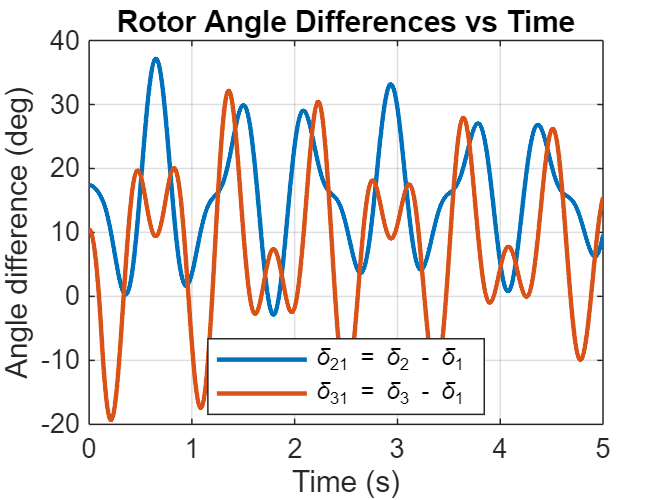


% Rotor angle history
delta_hist = x_hist(1:3, :);   % rows 1 to 3 are rotor angles in rad

% angle differences in radians
delta_21 = delta_hist(2,:) - delta_hist(1,:);
delta_31 = delta_hist(3,:) - delta_hist(1,:);

% convert to degrees
delta_21_deg = rad2deg(delta_21);
delta_31_deg = rad2deg(delta_31);

figure;
plot(t, delta_21_deg, 'LineWidth', 1.5); hold on;
plot(t, delta_31_deg, 'LineWidth', 1.5);
grid on;
xlabel('Time (s)');
ylabel('Angle difference (deg)');
title('Rotor Angle Differences vs Time');
legend('\delta_{21} = \delta_2 - \delta_1', ...
       '\delta_{31} = \delta_3 - \delta_1', ...
       'Location', 'best');